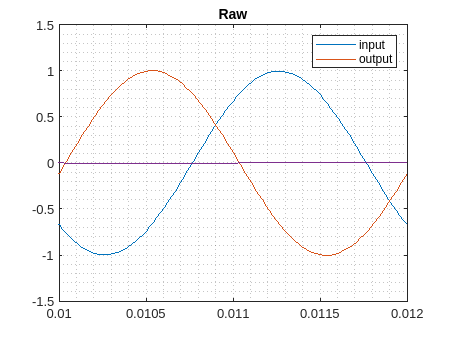

clear
close all
clc

data = load('log.DAS.20240501094908.txt');
inputData = data(:,1);
output_ula1 = data(:,2);
output_ula2 = data(:,3);
output_ula3 = data(:,4);
fs = 48e3;
t = 0:1/fs:(length(data)-1)/fs;
plot(t,inputData)
hold on
plot(t,output_ula1)
plot(t,output_ula2)
plot(t,output_ula3)
xlim([0.01 0.012])
grid minor
legend('input', 'output')
title('Raw')
hold off

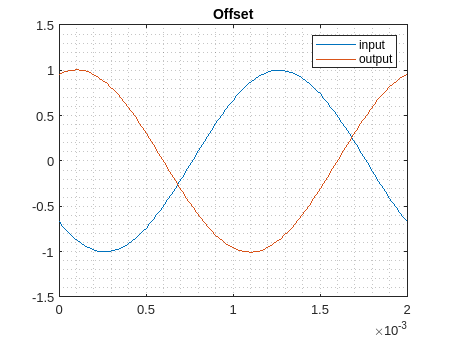


delayLength = 21; % HVORFOR 21??
plot(t(1:end-delayLength),inputData(1:end-delayLength))
hold on
plot(t(1:end-delayLength),output_ula1(delayLength+1:end))
xlim([0.0 0.002])
grid minor
legend('input', 'output')
title('Offset')
hold off

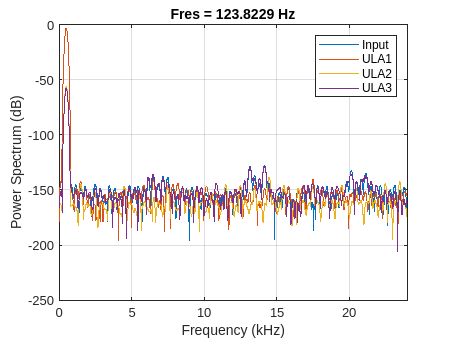


%spectrogram(inputData,fs)
%pwelch(inputData)
pspectrum(inputData,fs)
hold on
pspectrum(output_ula1,fs)
pspectrum(output_ula2,fs)
pspectrum(output_ula3,fs)
legend('Input', 'ULA1', 'ULA2', 'ULA3')
hold off